# Phase 2: Noise Characterization and Sigma Estimation

%% Phase 2: Noise Characterization and Sigma Estimation
% This script:
% 1. Loads BrainWeb T1 volumes (pn0, pn3, pn5, pn9)
% 2. Builds a brain mask from pn0
% 3. Normalizes all volumes using pn0 max intensity
% 4. Computes noise volumes n_X = pnX - pn0
% 5. Extracts noise inside the brain mask
% 6. Estimates Gaussian mu and sigma
% 7. Validates Gaussianity (histogram + QQ)
% 8. Saves sigma values for later phases

clear; clc;

% Set up directories

dataDir = fullfile('data', 'raw');
outDir  = fullfile('results','phase2');
figDir  = fullfile(outDir,'figures');
matDir  = fullfile(outDir,'mat');

if ~exist(outDir, 'dir'); mkdir(outDir); end
if ~exist(figDir,'dir'); mkdir(figDir); end
if ~exist(matDir,'dir'); mkdir(matDir); end

%% File names EXACTLY as in your folder

fn_pn0 = 't1_icbm_normal_1mm_pn0_rf0.nii';
fn_pn3 = 't1_icbm_normal_1mm_pn3_rf0.nii';
fn_pn5 = 't1_icbm_normal_1mm_pn5_rf0.nii';
fn_pn9 = 't1_icbm_normal_1mm_pn9_rf0.nii';

fileMap = containers.Map( ...
    {'pn0','pn3','pn5','pn9'}, ...
    {fn_pn0, fn_pn3, fn_pn5, fn_pn9} ...
);

noiseLevels = [0 3 5 9];

% Load pn0 and build brain mask

fprintf('Loading clean volume (pn0)...\n');

Loading clean volume (pn0)...


cleanVol = niftiread(fullfile(dataDir, fileMap('pn0')));
cleanVol = double(cleanVol);

% Determine global max for normalization
cleanMax = max(cleanVol(:));

% Normalize pn0
cleanVol = cleanVol / cleanMax;

% Estimate background value (BrainWeb uses constant outside brain)
vals   = cleanVol(:);
bg_val = mode(vals);

brainMask = cleanVol ~= bg_val;   % 1 inside brain, 0 outside

save(fullfile(matDir, 'brain_mask.mat'), 'brainMask', 'bg_val');

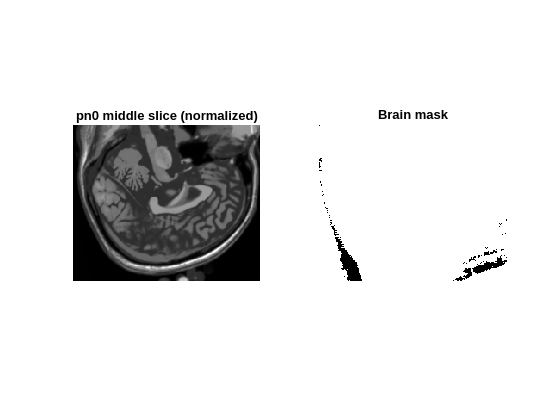

% Visual check — middle slice + mask overlay

sz = size(cleanVol);
mid = round(sz(3)/2);

figure;
subplot(1,2,1);
imagesc(cleanVol(:,:,mid)); axis image off; colormap gray;
title('pn0 middle slice (normalized)');

subplot(1,2,2);
imagesc(brainMask(:,:,mid)); axis image off; colormap gray;
title('Brain mask');
saveas(gcf, fullfile(figDir, 'pn0_brain_mask_slice.png'));


Processing pn0...


  mu:     0.000000


  sigma:  0.000000


  N:      6554384


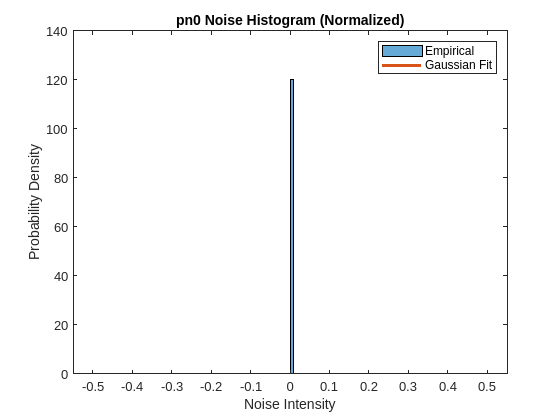

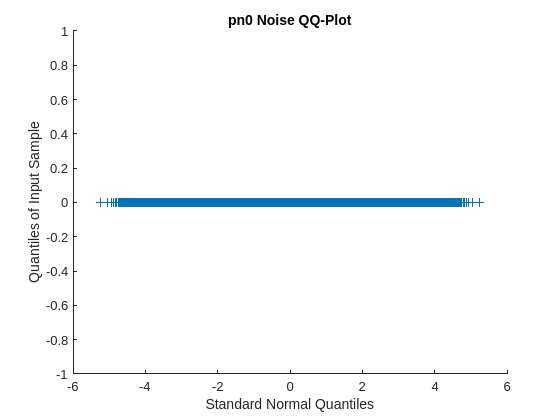


Processing pn3...


  mu:     -0.020369


  sigma:  0.056087


  N:      6554384


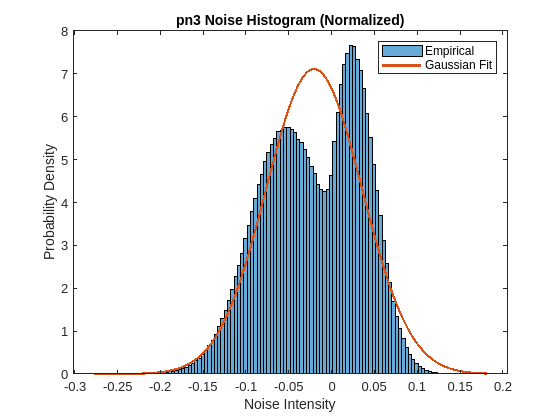

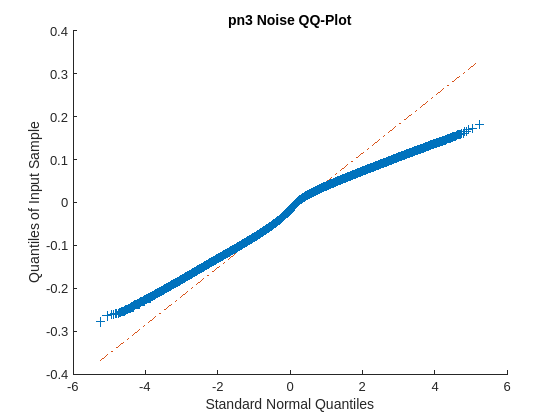


Processing pn5...


  mu:     -0.027279


  sigma:  0.087867


  N:      6554384


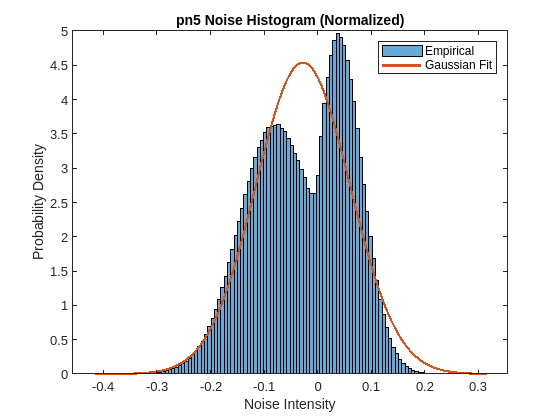

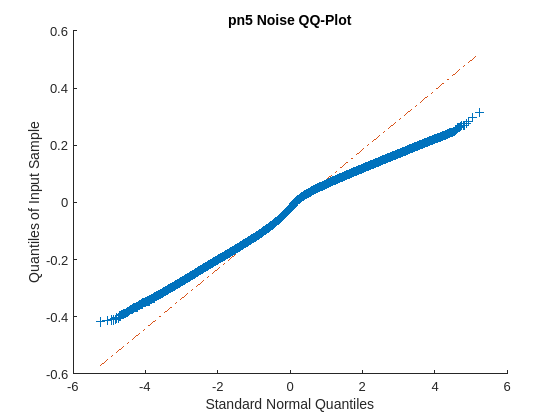


Processing pn9...


  mu:     -0.033547


  sigma:  0.141904


  N:      6554384


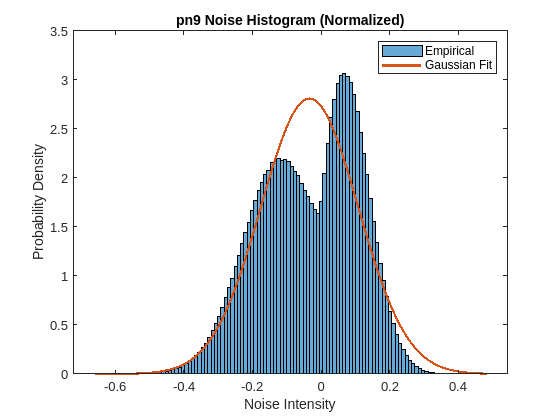

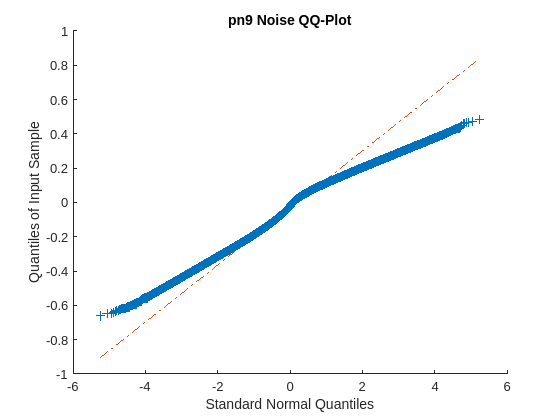

% Compute noise statistics for each noise level

noiseStats = struct('noiseLevel',[], 'mu',[], 'sigma',[], 'numSamples',[]);
idx = 1;

for nl = noiseLevels
    label = sprintf('pn%d', nl);
    fprintf('\nProcessing %s...\n', label);

    % Load noisy volume and normalize with SAME cleanMax
    noisyVol = niftiread(fullfile(dataDir, fileMap(label)));
    noisyVol = double(noisyVol);
    noisyVol = noisyVol / cleanMax;  % IMPORTANT FIX

    % Noise = noisy - clean
    noiseVol = noisyVol - cleanVol;

    % Extract noise only from brain region
    noiseBrain = noiseVol(brainMask);

    % Compute stats
    mu    = mean(noiseBrain);
    sigma = std(noiseBrain);
    N     = numel(noiseBrain);

    fprintf('  mu:     %.6f\n', mu);
    fprintf('  sigma:  %.6f\n', sigma);
    fprintf('  N:      %d\n', N);

    noiseStats(idx).noiseLevel = nl;
    noiseStats(idx).mu         = mu;
    noiseStats(idx).sigma      = sigma;
    noiseStats(idx).numSamples = N;

    % Histogram + Gaussian Fit
    figure;
    histogram(noiseBrain, 120, 'Normalization', 'pdf'); hold on;

    x = linspace(min(noiseBrain), max(noiseBrain), 400);
    y = normpdf(x, mu, sigma);
    plot(x, y, 'LineWidth', 1.6);

    xlabel('Noise Intensity');
    ylabel('Probability Density');
    title(sprintf('%s Noise Histogram (Normalized)', label));
    legend('Empirical', 'Gaussian Fit');

    saveas(gcf, fullfile(figDir, sprintf('%s_noise_hist.png', label)));

    % QQ-plot
    figure;
    qqplot(noiseBrain);
    title(sprintf('%s Noise QQ-Plot', label));
    saveas(gcf, fullfile(figDir, sprintf('%s_noise_qqplot.png', label)));

    idx = idx + 1;
end

% Save sigma values
save(fullfile(matDir, 'sigma_values.mat'), 'noiseStats');

% Display results as table in Live Script
T = struct2table(noiseStats);
disp('Final Noise Statistics (after correct normalization):');

Final Noise Statistics (after correct normalization):


disp(T);

    noiseLevel       mu         sigma      numSamples
    __________    _________    ________    __________

        0                 0           0    6.5544e+06
        3         -0.020369    0.056087    6.5544e+06
        5         -0.027279    0.087867    6.5544e+06
        9         -0.033547      0.1419    6.5544e+06

